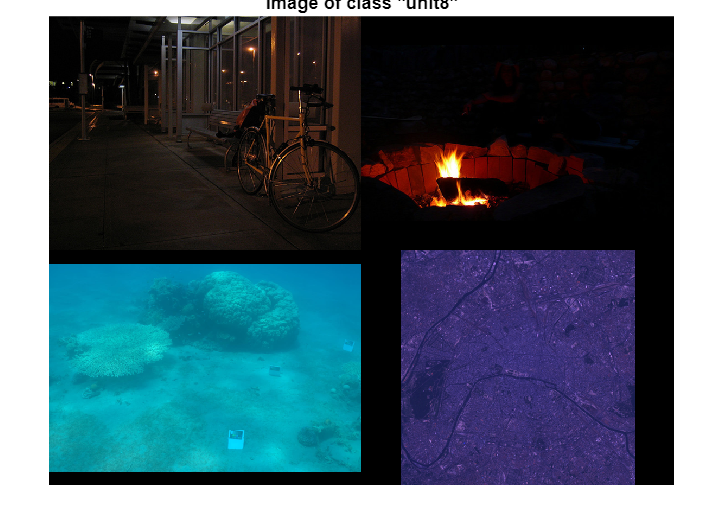

clear all;
addpath('C:\Users\JT\OneDrive - UNIR\UNIR\Primer Cuatrimestre\Percepcion Computacional\Actividades\Computational_Perception\Lab1');

% leer la imagen
I1 = imread('image1.png');
I2 = imread('image2.jpg');
I3 = imread('image3.jpg');
I4 = imread('image4.tif');

montage({I1,I2,I3, I4});title('Image of class "unit8"')

%imtool(I)
% J1 = single(I1);
% figure;
% imshow(J1,[]);title('Image of class "single"')

# Transformación logaritmo

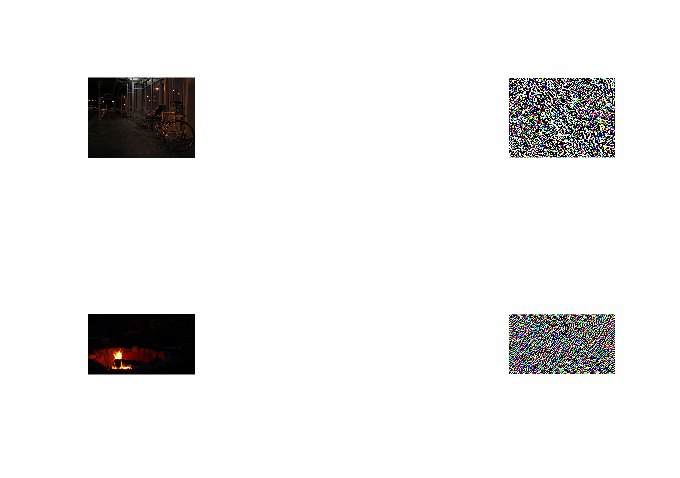

% calculamos la transformada de Fourier mediante la función fft2
F = fft2(I1);
Fc=fftshift(F); % mover el origen de la transformada al centro de la imagen

F2= fft2(I2);
F2c = fftshift(F2);


% hallar la transformación logaritmo
logT=log(1+abs(Fc));
phi = atan2(imag(F),real(F));

logT2=log(1+abs(F2c));
phi2 = atan2(imag(F2),real(F2));

% mostrar los resultados 
subplot(241)
imshow(I1)
subplot(242)
imshow(abs(Fc), [])
subplot(243)
imshow(logT, [])
subplot(244)
imshow(phi, [])

subplot(245)
imshow(I2)
subplot(246)
imshow(abs(F2c), [])
subplot(247)
imshow(logT2, [])
subplot(248)
imshow(phi2, [])

# Estiramiento de contraste

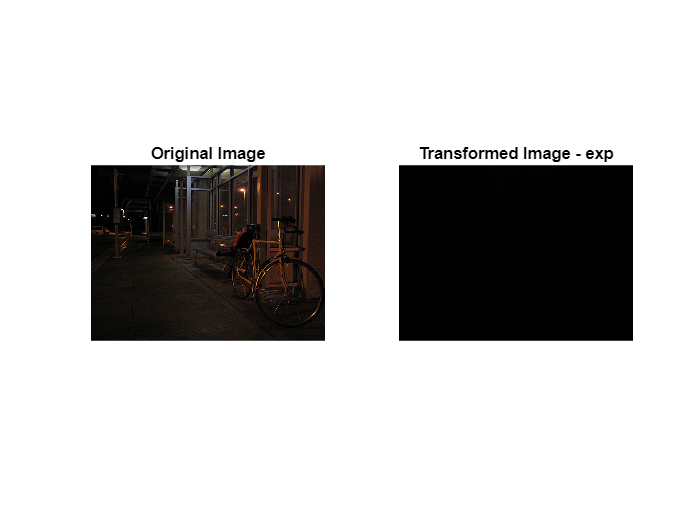

% Example usage:
% Load an example image
originalImage = imread('image1.png');

% Display the original image
figure;
subplot(1, 2, 1), imshow(originalImage), title('Original Image');

% Example 1: Gamma Correction
gammaValue = 1.5;
imageTransformations(originalImage, 'gamma', gammaValue);

% Example 2: Logarithmic Transformation
logParameter = 0.1;
imageTransformations(originalImage, 'log', logParameter);

% Example 3: Exponential Transformation
expParameter = 0.005;
imageTransformations(originalImage, 'exp', expParameter);

function transformedImage = imageTransformations(inputImage, transformationType, parameter)
    % Perform image transformations
    
    % Convert the input image to double
    inputImage = double(inputImage);
    
    % Size of the input image
    [rows, cols] = size(inputImage);
    
    % Initialize the transformed image
    transformedImage = zeros(rows, cols);
    
    % Apply the selected transformation
    switch transformationType
        case 'gamma'
            % Gamma correction
            transformedImage = 255 * (inputImage / 255).^parameter;
        case 'log'
            % Logarithmic transformation
            transformedImage = parameter * log(1 + inputImage);
        case 'exp'
            % Exponential transformation
            transformedImage = exp(parameter * inputImage);
        otherwise
            error('Invalid transformation type. Use ''gamma'', ''log'', or ''exp''.');
    end
    
    % Ensure the transformed image is in the valid intensity range [0, 255]
    transformedImage = min(max(transformedImage, 0), 255);
    
    % Convert the transformed image to uint8 for display
    transformedImage = uint8(transformedImage);
    
    % Display the original and transformed images
    subplot(1, 2, 1), imshow(uint8(inputImage)), title('Original Image');
    subplot(1, 2, 2), imshow(transformedImage), title(['Transformed Image - ' transformationType]);
end


function visualizeFourierTransform(image)
    % Perform Fourier transform
    F = fft2(image);
    Fc = fftshift(F); % Move the origin of the transform to the center of the image

    % Calculate the logarithmic transformation
    logT = log(1 + abs(Fc));
    phi = atan2(imag(F), real(F));

    % Display the results
    subplot(2, 4, 1)
    imshow(image)
    title('Original Image')

    subplot(2, 4, 2)
    imshow(abs(Fc), [])
    title('Magnitude Spectrum')

    subplot(2, 4, 3)
    imshow(logT, [])
    title('Logarithmic Transformation')

    subplot(2, 4, 4)
    imshow(phi, [])
    title('Phase Spectrum')
end

% % Load your image (replace 'your_image.jpg' with your image file)
% f = imread('your_image.jpg');
% 
% % Convert to grayscale if necessary
% f = rgb2gray(f);